clc;
clear;

syms theta phi
r = 4;
f = 13e9;
c = 3e8;
lambda = c/f;
B = (2*pi)/lambda;
w = 2*pi*f;
e0 = 8.854e-12;
n = B/(w*e0);
dl = lambda/50; %length of antenna
%dt= 1/f/20;
I0 = 1;

% Fields and Power Expression

E1 = 1i*n*I0*dl/(4*pi*r);
E2 = sin(theta);
E3 = exp(-1i*B*r);
E = E1*E2.*E3;

H1 = 1i*I0*dl/(4*pi*r);
H2 = sin(theta);
H3 = exp(-1i*B*r);
H = H1*H2.*H3;

P = real(E.*conj(H))/2;

% Transform

x = r.*sin(theta).*cos(phi);
y = r.*sin(theta).*sin(phi);
z = r.*cos(theta);

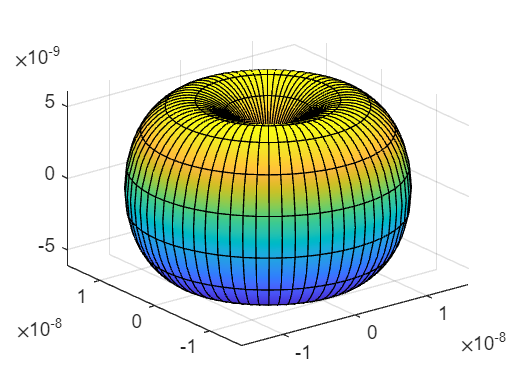

%  Power PLot
p_x = abs(P).*sin(theta).*cos(phi);
p_y = abs(P).*sin(theta).*sin(phi);
p_z = abs(P).*cos(theta);

fsurf(p_x,p_y,p_z,[0 pi 0 2*pi]);

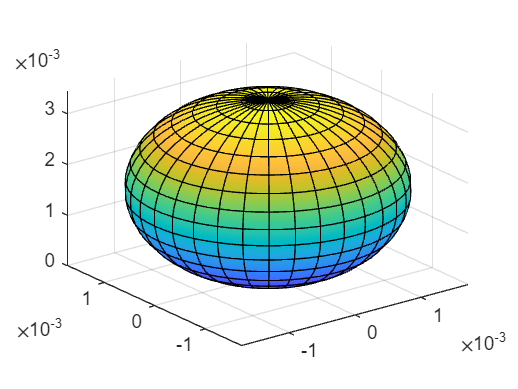

% Electric field

e_x = abs(E).*cos(theta).*cos(phi);
e_y = abs(E).*cos(theta).*sin(phi);
e_z = abs(E).*sin(theta);

fsurf(e_x,e_y,e_z,[0 2*pi 0 pi]);

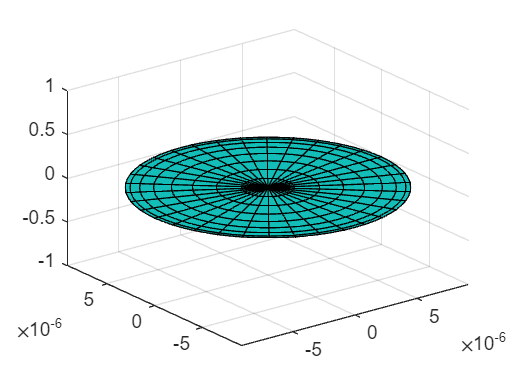

% Magnetic Field Plot

x_h = -abs(H)*cos(phi);
y_h = abs(H)*sin(phi);
z_h = 0;

fsurf(x_h,y_h,z_h,[0 2*pi]);

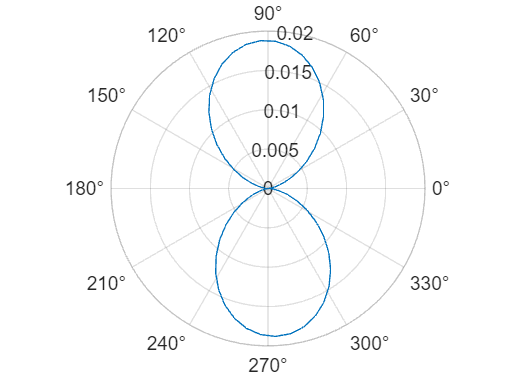

theta=0:0.1:2*pi;
phi=0:0.1:2*pi;
urad = (n/2)*(((B*I0*dl)/(4*pi))*sin(theta)).^2;
polarplot(urad);